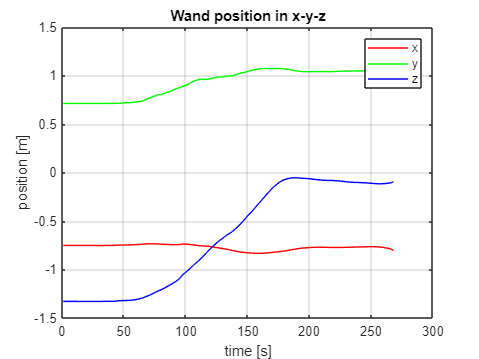

clear

Path = 'C:\Users\PervasiveComputing\Desktop\LNDF_22\Logs\LNF_Traj.csv';

% Get Waypoint from csv sheet
Table = readtable(Path);
time = table2array(Table(:, 2));
x_wand = table2array(Table(:, 3));
y_wand = table2array(Table(:, 4));
z_wand = table2array(Table(:, 5));
x_drone = table2array(Table(:, 6));
y_drone = table2array(Table(:, 7));
z_drone = table2array(Table(:, 8));

length = size(x_wand, 1);

figure
plot(x_wand, 'red')%, 'XData',time)
grid
hold on
plot(y_wand,'green')%,'XData',time)
plot(z_wand,'blue')%,'XData',time)
title 'Wand position in x-y-z'
xlabel 'time [s]'
ylabel 'position [m]'
legend 'x' 'y' 'z'
hold off

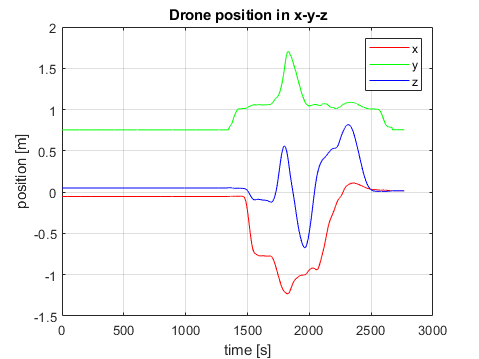


figure
plot(x_drone, 'red')%, 'XData',time)
grid
hold on
plot(y_drone,'green')%,'XData',time)
plot(z_drone,'blue')%,'XData',time)
title 'Drone position in x-y-z'
xlabel 'time [s]'
ylabel 'position [m]'
legend 'x' 'y' 'z'
hold off

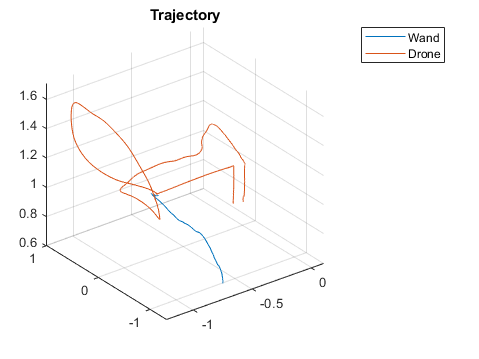


figure
plot3(x_wand, z_wand, y_wand)
grid
hold on
plot3(x_drone, z_drone, y_drone)
title 'Trajectory'
legend 'Wand' 'Drone'